# Lecture #6 Notes

# Low Dimensional Visualization and Clustering                                  

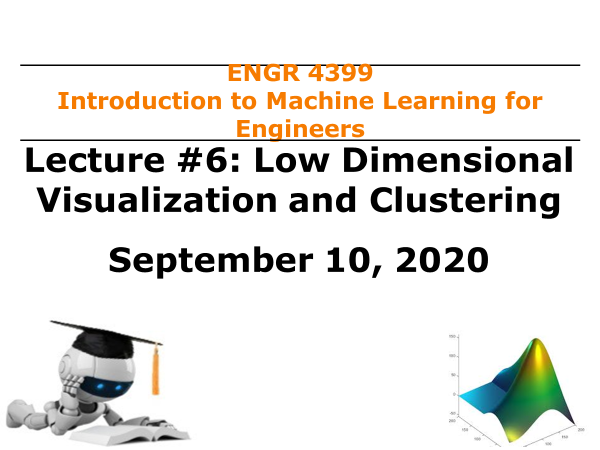

## Process to Develop Machine Learning Algorithms

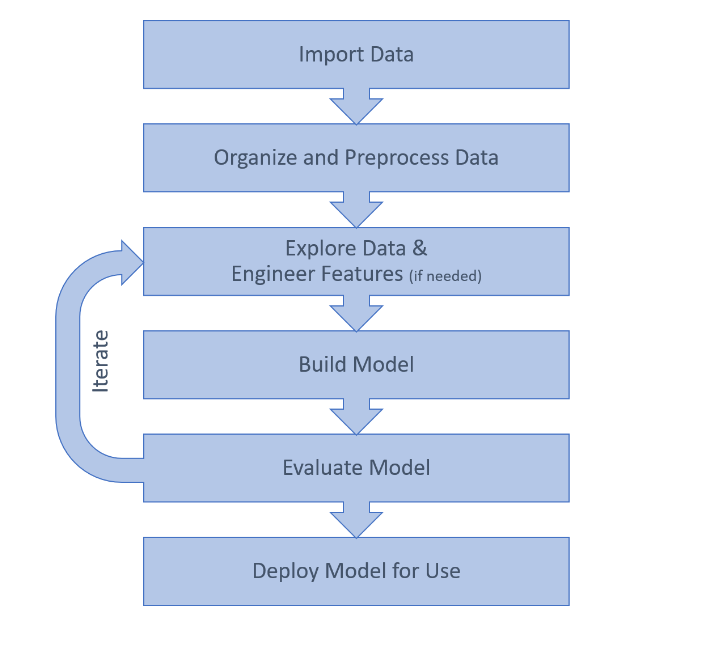

## Identifying Groups by Visualizing Data

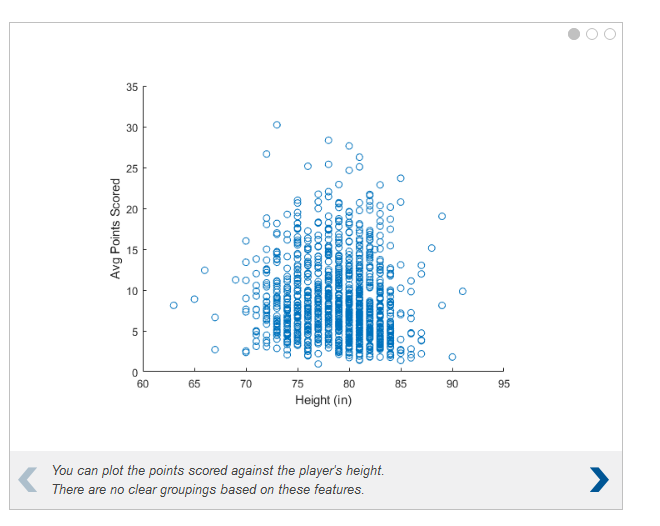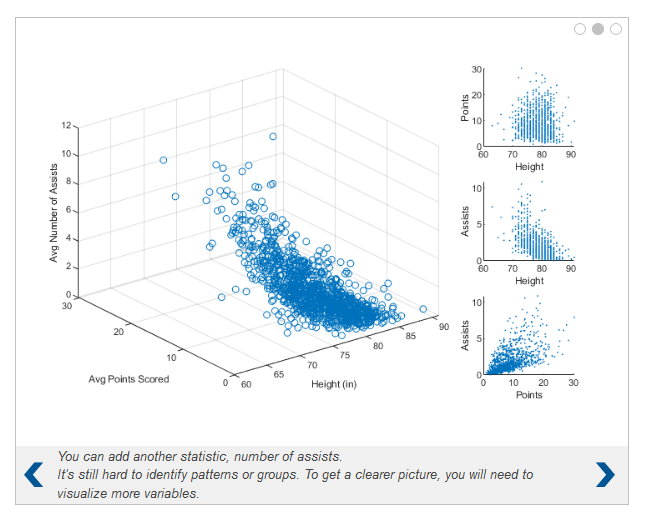

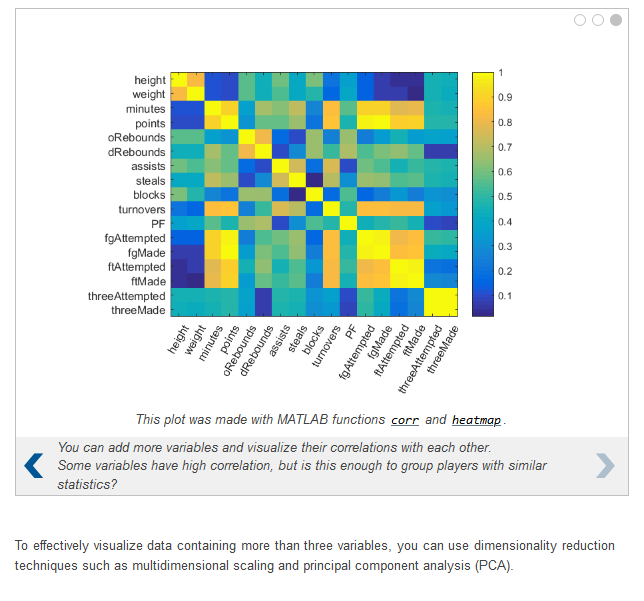

## Classical Multidimensional (CMD) Scaling for Dimensionality Reduction

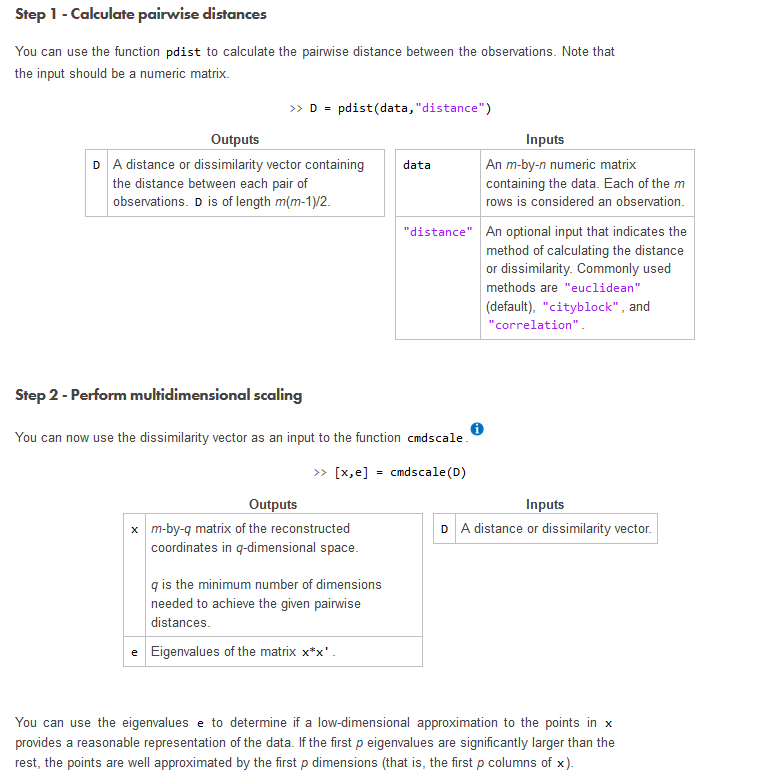

### Classical Multidimensional Scaling

Import data using the load command

load CMSData
whos

### Step 1: Calculate the pairwise distance between rows of X and name it D.

D = pdist(X);
whos

### CMDscale

### Step 2: Calculate the configuration matrix and eigenvalues of the distance matrix D, and name them Y and e.

[Y,e] = cmdscale(D);
whos

### Step 3: Create a Pareto chart of the eigenvalue elements

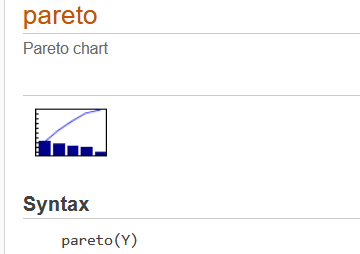

Pareto charts display the values in the vector `Y` as bars drawn in descending order. Values in `Y` must be nonnegative and not include `NaN`s. By default, either the tallest 10 bars or first 95% of the cumulative distribution is displayed, whichever is smaller.

y = [ 90 75 30 60 5 40 40 5];
pareto(y)

Create a pareto chart of the eigenvalues

pareto(e)

From the Pareto chart, you can see that 100% of the distribution is described in three variables.

You can use the scatter3 function to create a three-dimensional scatter plot.

### Step 4: Create a scatter plot using the first three columns of Y.

scatter3(Y(:,1),Y(:,2),Y(:,3))

### Step 5: Create a scatter plot using the first two columns of Y.

scatter(Y(:,1),Y(:,2))

## Principal Component Analysis (PCA) for Dimensionality Reduction

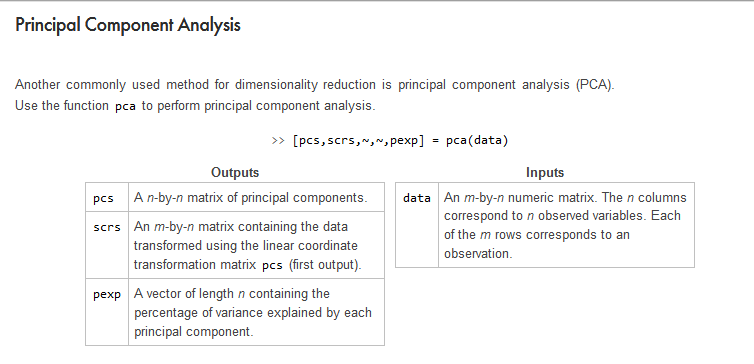

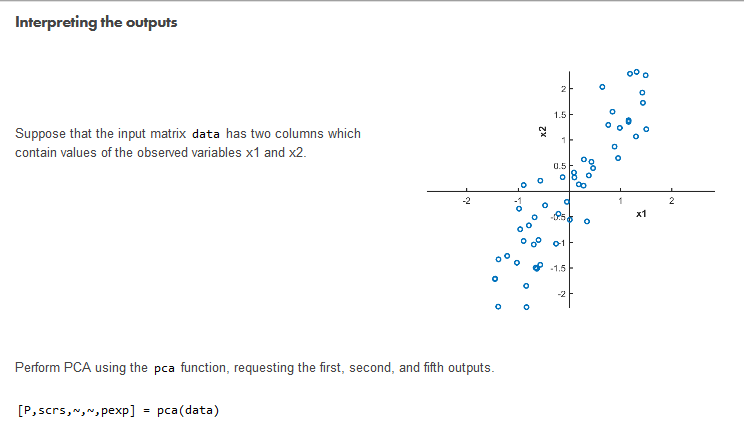

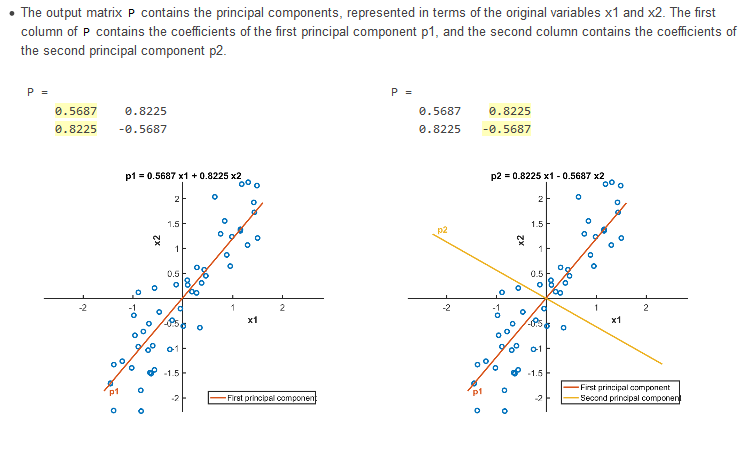

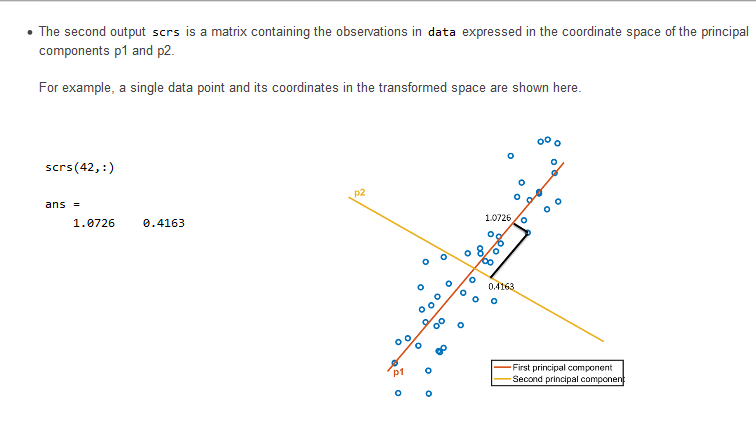

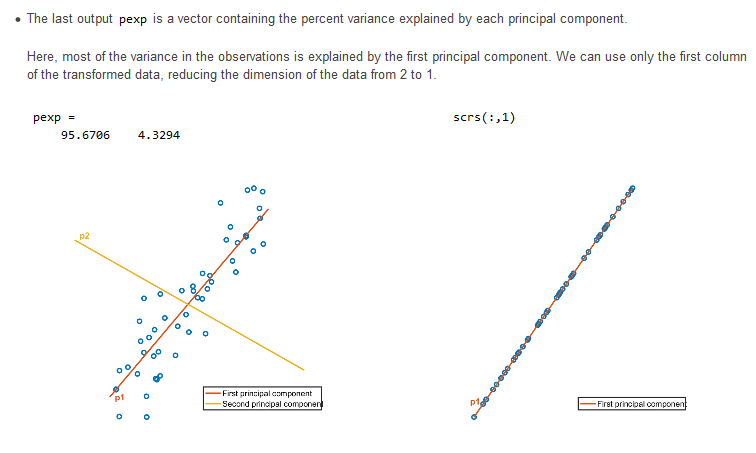

#### Principal Component Analysis

Import data

load PCAData
whos

#### Task 1: Use the pca function to perform principal component analysis on raw data.

                             Syntax:    [coeff,score,~,~,expl] = pca(observations);

Calculate the principal component coefficients, pcs, 

principal component scores, scrs, 

percentage of total variance explained by each principal component of each variable, pexp, of X.

[pcs,scrs,~,~,pexp] = pca(X)
whos

#### Task 2: Create a Pareto chart with the variance explained values.

    pareto(pexp)

####  Task 3: Create a two-dimensional scatter plot using the data in scrs.

scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
scatter(scrs(:,1),scrs(:,2))

load statsNorm.mat
labels

## **In-Class #6: CMD and PCA Dimensionality Reduction**

## TODO - TASK 1: Use CMD scaling, then plot the pareto chart and a 3-D scatter plot

Use Classical Multidimensional (CMD) scaling to find the reconstructed coordinates and corresponding eigenvalues.

D = pdist(statsNorm);
[Y,e] = cmdscale(D);
pareto(e)
scatter3(Y(:,1),Y(:,2),Y(:,3))
labels{1:3}
view(110,40) %rotate view of scatter plot

## TODO - TASK 2: Use PCA, then plot the pareto chart and a 3-D scatter plot

Use Principal Component Analysis (PCA) principal component scores and the percentage of total variance explained by each principal component of each variable in statsNorm.

[pcs,scrs,~,~,pexp] = pca(statsNorm);
pareto(pexp)
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
view(110,40)
